# TNA005: Tillämpad matematik i teknik och naturvetenskap

## Examination: UPG9 Introduktion till MATLAB

## Datum: 2021-08-20

## Namn: förnamn efternamn 

## Personnummer: yyyymmdd-xxxx

## LiU-ID: abcde???

## Klass: ???

## Uppgift 1

Förklara din kod antingen här, eller som kommentarer i kod-blocken. 

% Skriv din kod här:
clear 
% a
% rand1 tar ints 1 - 4
n = 4 + randi(4)

n = 8

A = zeros(n)

A =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


for i = 1:n
    for j = 1:n
        A(i, j) = 1/(i+j-1);
    end
end
A

A =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667


% b
r = rand(n, 1)

r =     0.9058
    0.1270
    0.9134
    0.6324
    0.0975
    0.2785
    0.5469
    0.9575


b = A*r

b =     1.6956
    1.0808
    0.8270
    0.6793
    0.5800
    0.5078
    0.4525
    0.4086


b

b =     1.6956
    1.0808
    0.8270
    0.6793
    0.5800
    0.5078
    0.4525
    0.4086


x = A\b

x =     0.9058
    0.1270
    0.9134
    0.6324
    0.0975
    0.2785
    0.5469
    0.9575



diff = abs(x - r)

diff = 	1.0e+-6 *

    0.0000
    0.0009
    0.0125
    0.0692
    0.1894
    0.2712
    0.1949
    0.0554


[maxAvikelse, indAvvikelse] = max(diff)

maxAvikelse = 2.7125e-07

indAvvikelse = 6

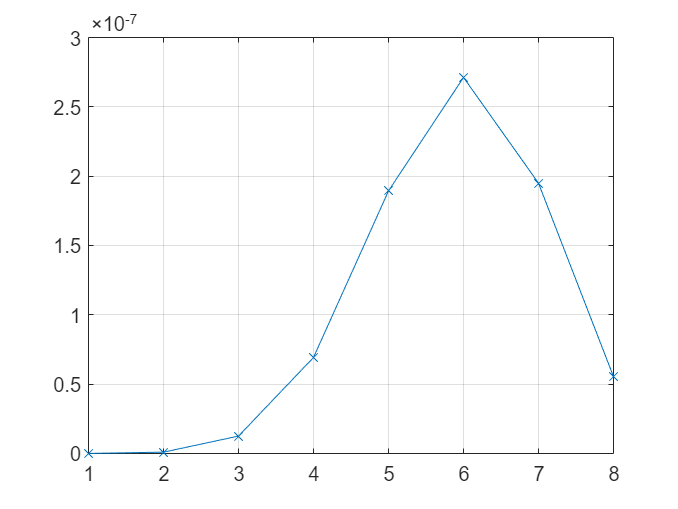

plot(diff, '-x'); 
grid on

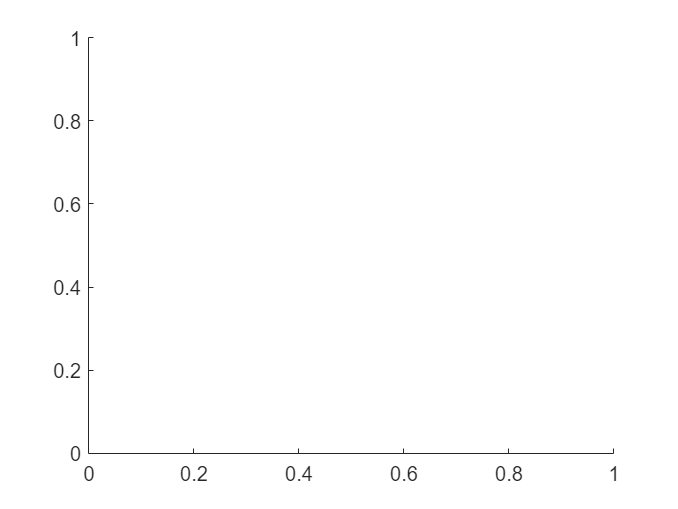

clf
cla

## Uppgift 2

Förklara din kod antingen här, eller som kommentarer i kod-blocken. 

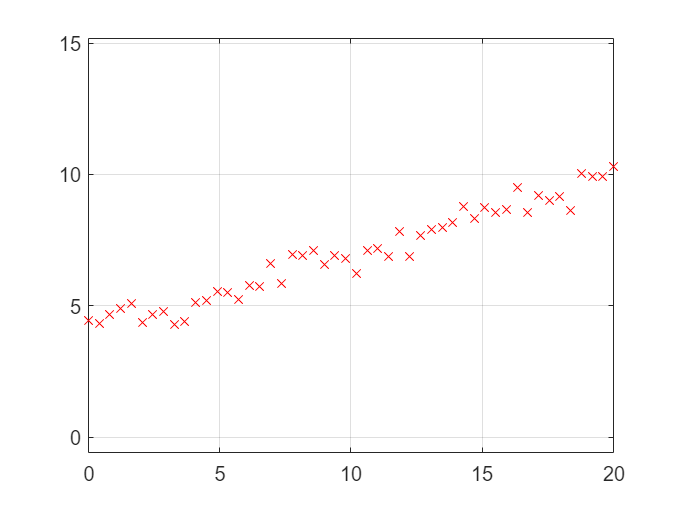

% Skriv din kod här:
clear 
%hold off
load('data20210820.mat')
plot(x, y, 'rx')
axis equal
grid on

% Förklara koden
% Dra slutsater och 
% svara på ställda frågor, 

xm = mean(x)

xm = 10

ym = mean(y)

ym = 6.9781

Sxx = sum((x-xm).*(x-xm))

Sxx = 1.7347e+03

Sxy = sum((x - xm) .* (y - ym))

Sxy = 509.0698

beta = Sxy/Sxx

beta = 0.2935

alpha = ym - beta*xm

alpha = 4.0435

linje = alpha + beta*x

linje =     4.0435
    4.1633
    4.2831
    4.4028
    4.5226
    4.6424
    4.7622
    4.8820
    5.0017
    5.1215


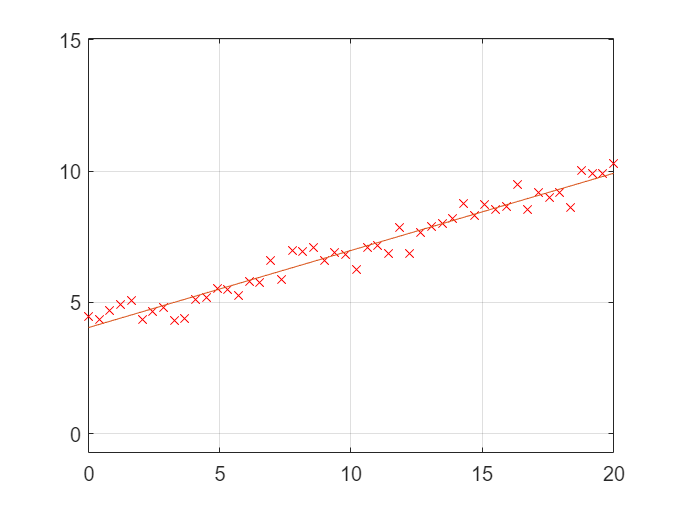

hold on
plot(x, linje, '-')

clf
cla

% c
ei = y - linje

ei =     0.4080
    0.1775
    0.4032
    0.5040
    0.5623
   -0.2918
   -0.1066
   -0.0818
   -0.6981
   -0.7324


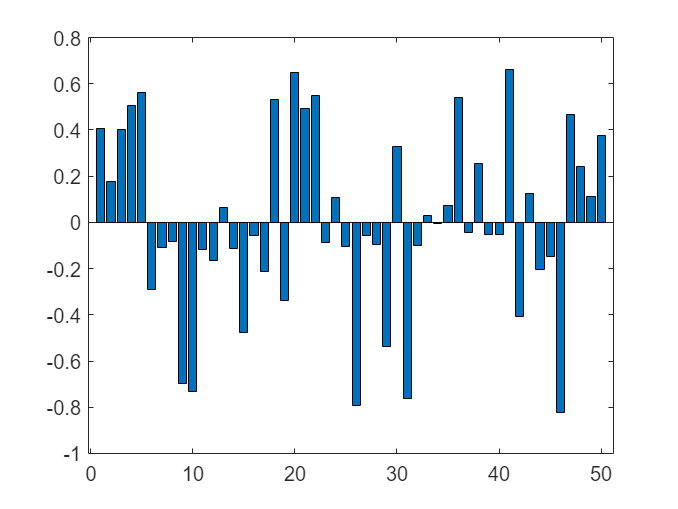

bar(ei)

## Uppgift 3

Förklara din kod antingen här, eller som kommentarer i kod-blocken.  

clear 
n = 9 + randi(11)

n = 20

fun = @(x) sin(x)

fun = function_handle with value:
    @(x)sin(x)


a = 0

a = 0

b = pi

b = 3.1416

I = duggaFunc(fun, a, b, n)

I = 1.9959


fel = abs(I - 2)

fel = 0.0041

clear
fun = @(x) sin(x);
a = 0;
b = pi;
n = 10;
I = duggaFunc(fun, a, b, n);
while abs(2 - I) > 1e-7
    n = n + 1;
    I = duggaFunc(fun, a, b, n);
end
n

n = 4056

format long
I

I =    1.999999900010917


abs(2 - I)

ans =      9.998908279129637e-08
